# Example of jsbutton

## 0. Introduction

`jsbutton` is a custom component which allows to insert buttons that are customizable with CSS via JavaScript® into a GUI. As an example, the screenshot below shows an app made with MATLAB® using multiple instances of `jsbutton`:

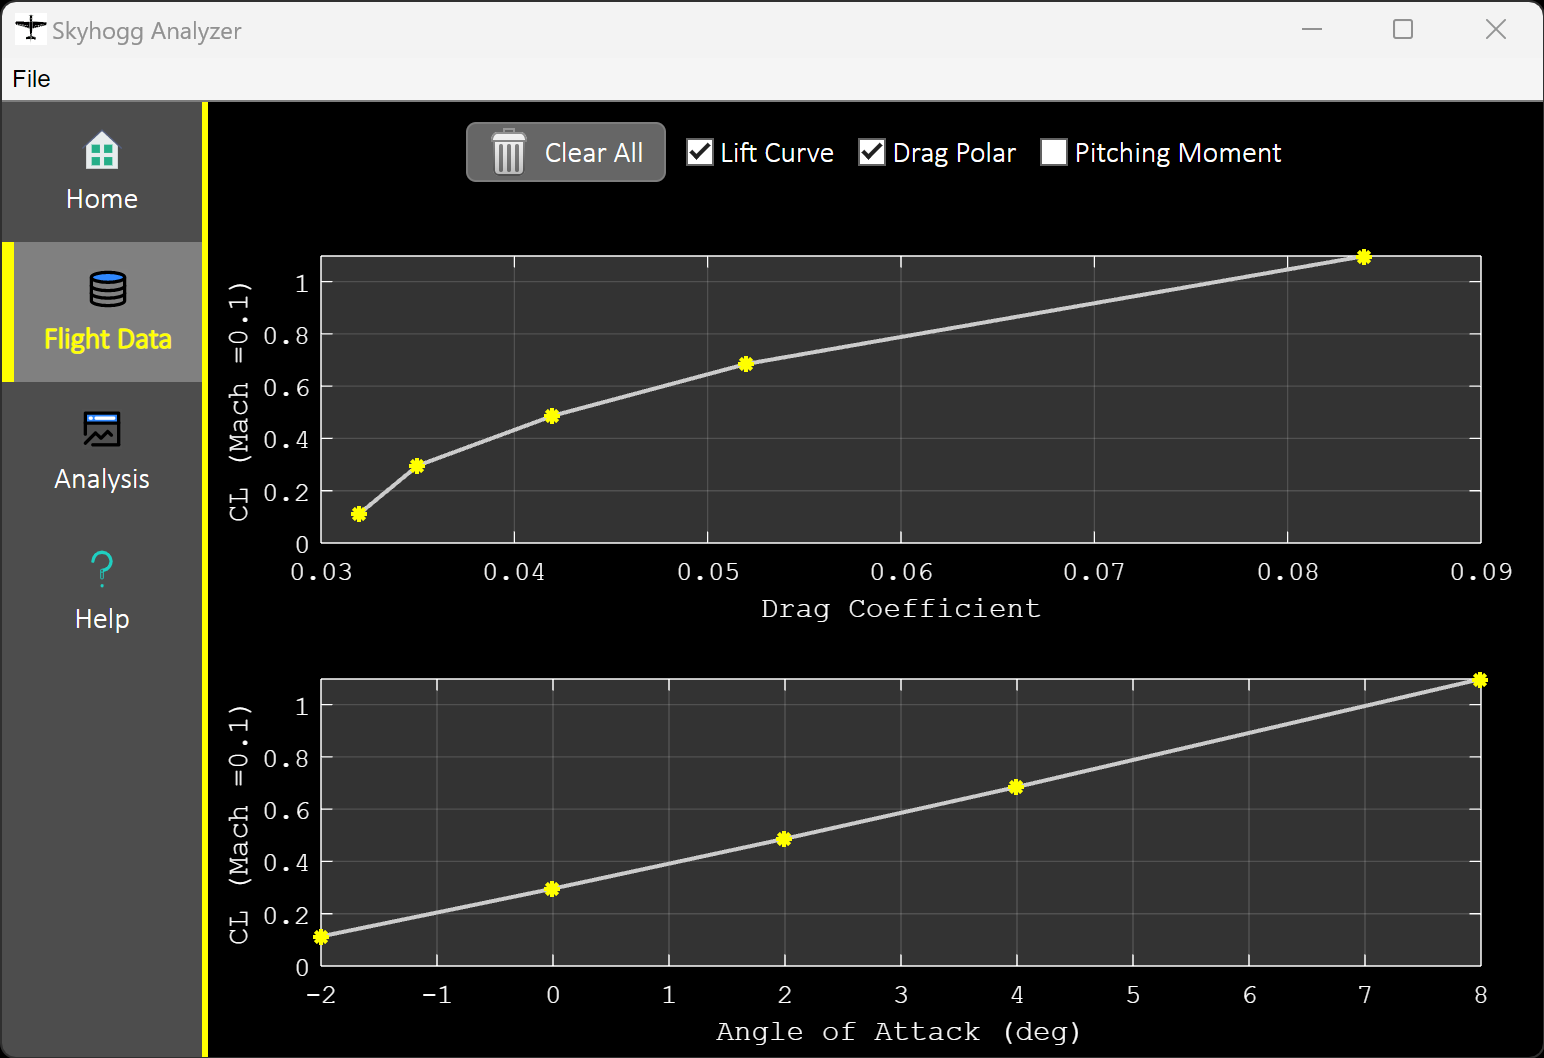

The following sections describe how to create an instance of `jsbutton` and how to customize its appearance and behavior.

## 1. Create An Instance Programmatically

There are two ways by which a `jsbutton` object can be created: with and without customizations included in the call to the class constructor.

### 1.1 Create Without Customizations

In this case, the only necessary input to the constructor function is the parent object, which can be any web-enabled container object, such as `uifigure`, `uigridlayout`, or `uipanel`.

fig = uifigure;
b = jsbutton(fig)

b =   jsbutton with properties:

         BorderBottomColor: [0.5000 0.5000 0.5000]
           BorderLeftColor: [0.5000 0.5000 0.5000]
          BorderRightColor: [0.5000 0.5000 0.5000]
            BorderTopColor: [0.5000 0.5000 0.5000]
     BorderBottomThickness: 1
       BorderLeftThickness: 1
      BorderRightThickness: 1
        BorderTopThickness: 1
              BorderRadius: 4
               ButtonColor: [0.9600 0.9600 0.9600]
     ButtonBackgroundColor: [0.9400 0.9400 0.9400]
                    Enable: 1
                 FontColor: [0 0 0]
                  FontName: "Helvetica"
                  FontSize: 12
                FontWeight: normal
           HoverFontWeight: normal
       HorizontalAlignment: center
    HoverBorderBottomColor: [0.5000 0.5000 0.5000]
      HoverBorderLeftColor: [0.5000 0.5000 0.5000]
     HoverBorderRightColor: [0.5000 0.5000 0.5000]
       HoverBorderTopColor: [0.5000 0.5000 0.5000]


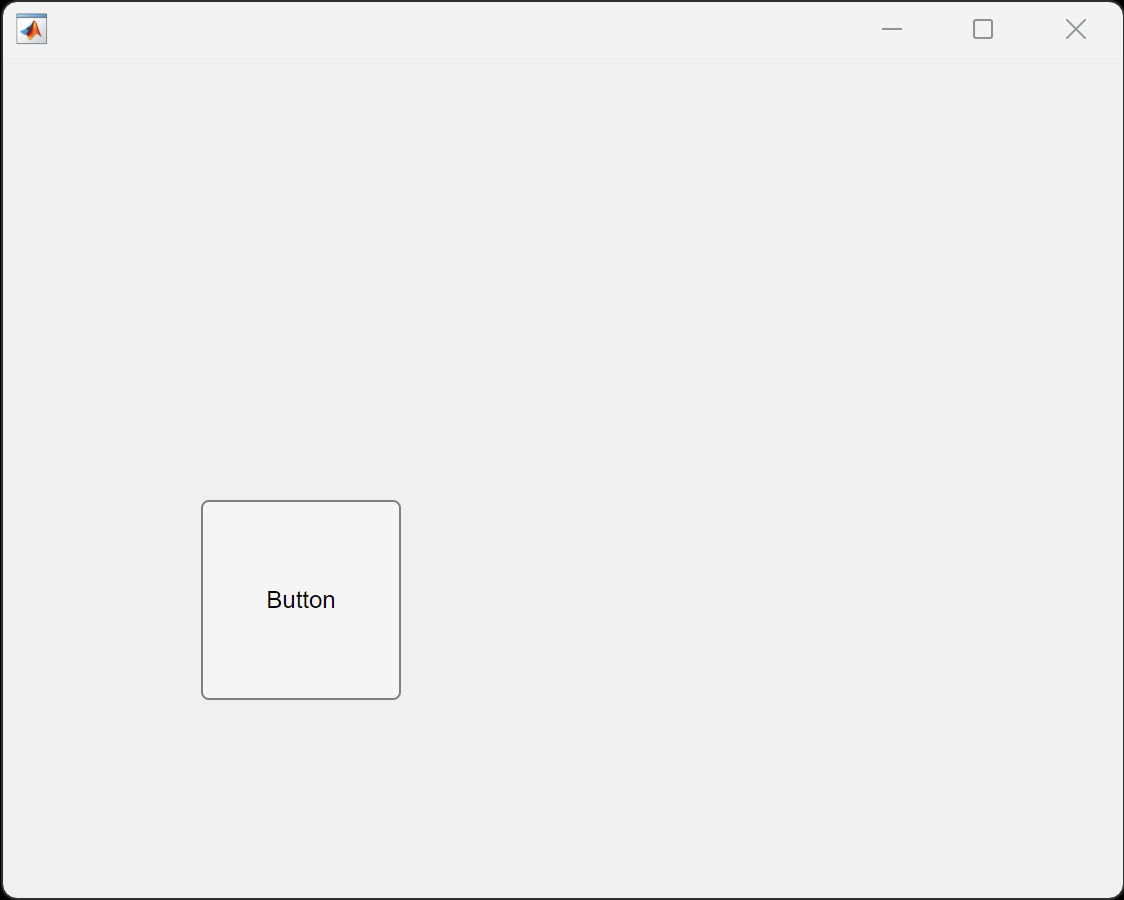

### 1.2 Create With Customizations

There are several public properties of `jsbutton` which allow to customize its appearance:

props = properties(b)

props = 52×1 cell array
    {'BorderBottomColor'     }
    {'BorderLeftColor'       }
    {'BorderRightColor'      }
    {'BorderTopColor'        }
    {'BorderBottomThickness' }
    {'BorderLeftThickness'   }
    {'BorderRightThickness'  }
    {'BorderTopThickness'    }
    {'BorderRadius'          }
    {'ButtonColor'           }
    {'ButtonBackgroundColor' }
    {'Enable'                }
    {'FontColor'             }
    {'FontName'              }
    {'FontSize'              }
    {'FontWeight'            }
    {'HoverFontWeight'       }
    {'HorizontalAlignment'   }
    {'HoverBorderBottomColor'}
    {'HoverBorderLeftColor'  }
    {'HoverBorderRightColor' }
    {'HoverBorderTopColor'   }
    {'HoverButtonColor'      }
    {'HoverTextColor'        }
    {'HoverTextUnderline'    }
    {'Icon'                  }
    {'IconAlignment'         }
    {'IconSize'              }
    {'Text'                  }
    {'ButtonPushedFcn'       }


In this case, in addition to the parent container specify optional name-value arguments including the public properties of `jsbutton` as Name=Value pairs in the call to the class constructor, for example:

fig = uifigure;
b = jsbutton(fig, BorderRadius=50, ButtonColor="black", FontColor="white", Text="Press me!", FontName="Calibri Light");

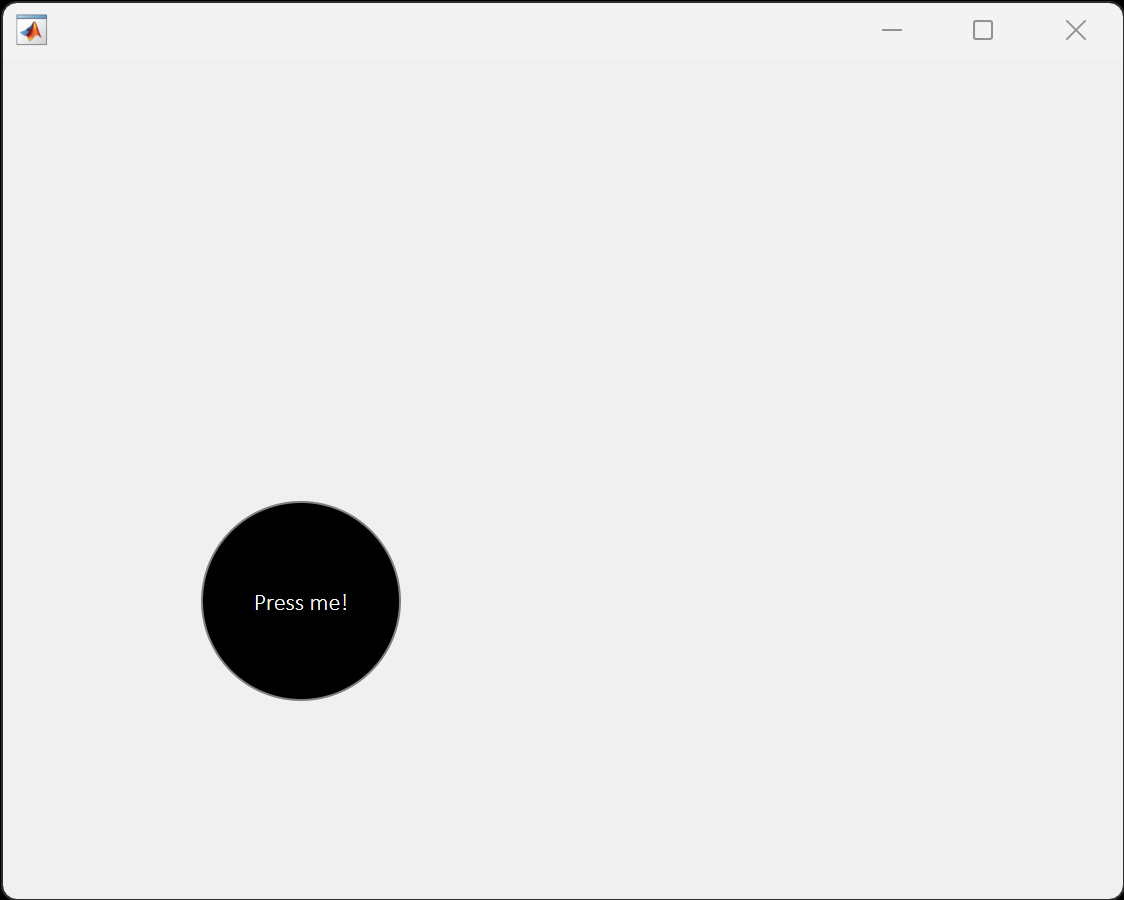

**Note:** it is possible to create an instance of `jsbutton` without specifying any input argument, however the parent will be left empty, so it will not be displayed anywhere on the screen. In order to assign it a parent at a later stage, it is necessary to create a handle to the object at initialization, and subsequently assign the `Parent` property.

## 2. Modify Properties and Define Behavior

After creating the object, it is possible to customize the button appearance and behavior if a handle variable is available in the workspace.

### 2.1 Modify Properties

 Below is an example showing how to modify the appearance by updating the values of the public properties:

% Modify one property
b.ButtonColor = "blue"; % (one can also use RGB representation with values from 0 to 1 or hexadecimal representation)

% Modify multiple properties
set(b, FontWeight = "bold", FontSize = 20)

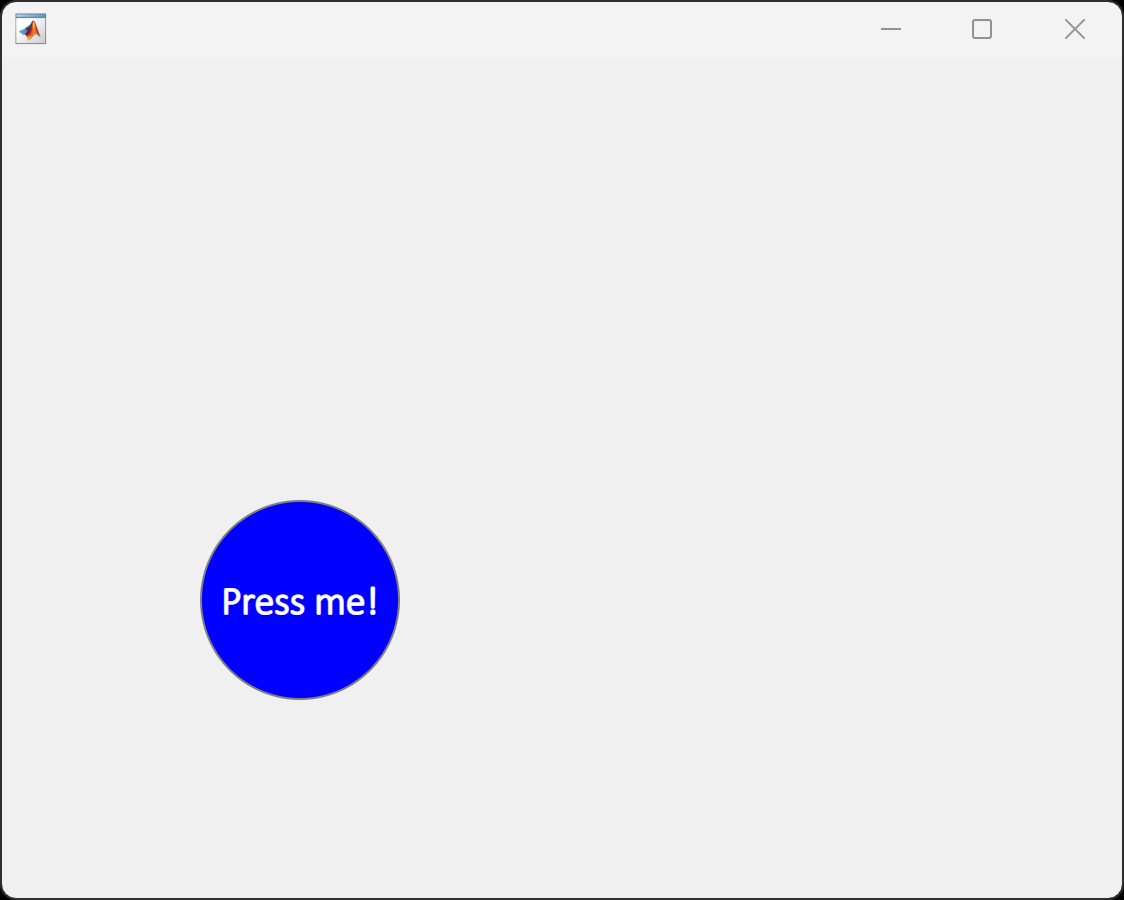

### 2.1 Define Behavior

To define the button behavior upon a click, assign a callback function by setting the `ButtonPushedFcn` property:

b.ButtonPushedFcn = @(~,~) disp('Button pressed');

## 3. Add To App Designer

Since `jsbutton` is a sub-class of `matlab.ui.componentcontainer.ComponentContainer` it is possible to package the object as a custom component of App Designer which can be dragged and dropped into the canvas. To do this, execute the following statement in the MATLAB Command Window:

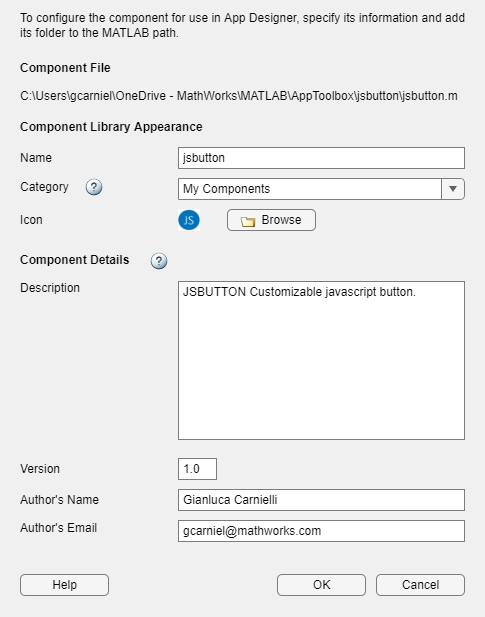

appdesigner.customcomponent.configureMetadata('jsbutton.m')

Follow the instructions and add the folder containing the source code to the path, so that the custom component remains available in App Designer, regardless of where the user is in the MATLAB path. Finally, inside App Designer the component should be available and it should appear like the screenshot below:

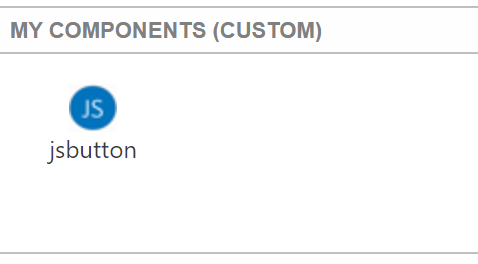

## 4. Add New Customizations

It is possible to define new CSS-compliant customizations to the button by adapting `jsbutton.m` and `button.js`. To add a new customization, proceed as follows:

- Define a new public property in `jsbutton.m` and include a default value (providing a default value is necessary for creating a custom component in App Designer), for example: "`NewProp double = 1`"

- Add a new line in the call to update the `Data` property of the HTML component in the `update` method of the `jsbutton` class, for example: "`NewProp = obj.NewProp, ...`"

- Add a new line in `button.js` to implement the new customization. For example, supposing that `NewProp` represents the font size, then the code would be updated as follows: "`'font-size: ' + html.Data.NewProp + 'px;',`" in the javascript variable `StyleProps`.

*Copyright 2023 The MathWorks, Inc.*